inputWeights = mlp.IW{1};
inputWeights = sum(abs(inputWeights))

inputWeights =     0.7858    0.6140    0.6567    0.6807    0.8682    0.6422    0.4447    0.4947    0.7458    0.4048    0.8246    0.5415    0.6243    0.6458    0.7140    0.4755    0.6677    0.6047    0.9412    0.7733    0.5499    0.5474    0.3713    0.5520    0.5423    0.3584    0.8271    0.4998    1.1783    0.4648    0.4757    1.1963    1.0166    0.8383    0.7572    0.8565    1.3346    0.9251    0.5593    1.1895    0.8439    0.4436    1.1896    2.3250    1.1936    0.6662    1.4064    0.8206    0.9670    0.5504


[maxWeight, idx] = max(inputWeights);
selectedFeature = features(idx,:)

selectedFeature =     6.4195    9.6208    8.6023    6.2981    8.2476    8.2569    5.5122    7.5112    5.0690    5.7975    7.3727    7.2660    6.9524    8.6293    6.8756    6.1904    7.6570    7.6862    6.6998    8.4409    7.5319    5.0145    7.1397    4.8732    6.5158    8.2995    8.1750    6.5767    8.6992    5.0142    6.0327    8.7300    6.9832    7.3296    8.5708    6.9945    5.3756    8.4032    6.1381    6.7535    9.5413    7.2890    8.8393    9.4791   10.1961    7.8191    8.7655    8.3225    5.0340    8.0581


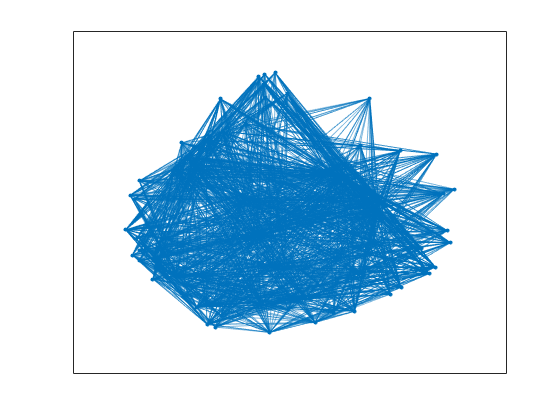

A = zeros(length(selectedFeature));
for i = 1:length(selectedFeature)
    for j = 1:length(selectedFeature)
        A(i,j) = abs(selectedFeature(i) - selectedFeature(j));
    end
end
A = (A>mean(A(:)));
G = graph(A);
plot(G);

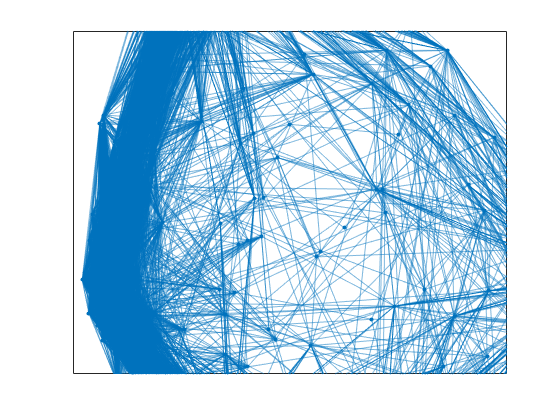

rho = corr(features');
p = 0.16;
rho = rho - diag(diag(rho));
rho = (rho > p);
G = graph(rho, 'upper');
plot(G)